## IE3032/BE3022 - Lección 2

### Sinusoides en tiempo discreto

Para evidenciar el comportamiento extraño de los sinusoides en tiempo discreto, iniciemos con la intuición que traemos de los sinusoides de tiempo continuo para ver cómo los sinusoides discretos rompen con esta intuición.

#### Experimento 1: periodicidad

Cualquier sinusoide continuo que generemos será periódico

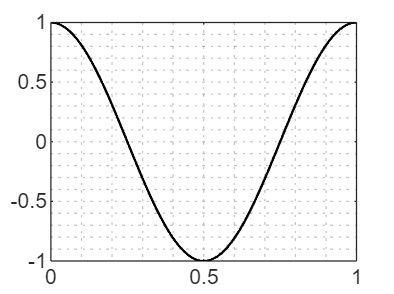

t = 0:0.001:1;
x_t = cos(2*pi*1*t +0);
figure;
plot(t, x_t, 'k', 'LineWidth', 1);
grid minor;

Sin embargo, al generar sinusoides discretos vemos que estos NO son necesariamente periódicos e inclusive tampoco presentan la forma "típica" de lo que esperamos en un sinusoide

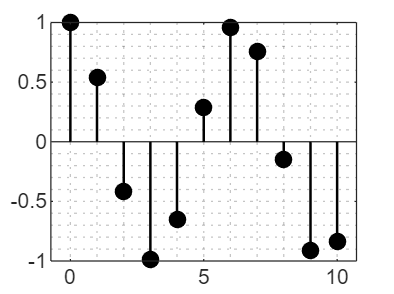

n = 0:10;
x_n = cos(1*n + 0);
figure;
stem(n, x_n, 'k', 'filled', 'LineWidth', 1);
grid minor;

Es más, resulta que los ÚNICOS sinusoides discretos periódicos son aquellos que reciben el nombre de armónicos. Estos presentan una frecuencia dada por

$\omega=\frac{2\pi k}{N}$,

donde tanto $k$ como $N$ son números enteros y $N$ es el período del sinusoide

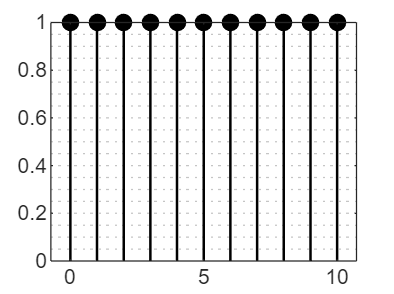

k = 0;
w = 2*pi*k/10;
x_n = cos(w*n);
figure;
stem(n, x_n, 'k', 'filled', 'LineWidth', 1);
grid minor;

#### Experimento 2: frecuencia

Supongamos que comenzamos con un sinusoide analógico $x_1$ a cierta  frecuencia y formamos un segundo, $x_2$, aumentando la frecuencia del primero. Intuitivamente, sabemos que el segundo sinusoide oscilará más rápido (presentará más oscilaciones en el mismo intervalo de tiempo) que el primero

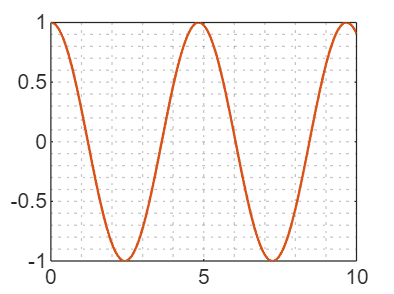

t = 0:0.01:10;
x1 = cos(1.3*t);
x2 = cos((1.3 + pi*0)*t);
figure;
plot(t, [x1', x2'], 'LineWidth', 1);
grid minor;

Sin embargo, si repetimos el mismo experimento en tiempo discreto observamos que el segundo sinusoide, aunque sea más rápido que el primero, se comporta de la misma manera. Decimos que el segundo sinusoide es un alias del primero ya que se comportan de la misma forma. Este fenómeno se conoce como aliasing

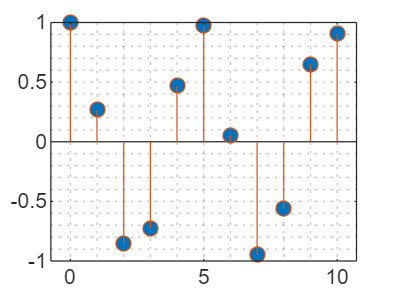

n = 0:10;
y1 = cos(1.3*n);
y2 = cos((1.3 + pi*0)*n);
figure;
stem(n, y1, 'filled');
hold on;
stem(n, y2);
grid minor;